layerfolder='../data/layers/';%route to folder with ambiental data
temp=dir(layerfolder);
layers={temp.name};
comp=strncmp('bio',layers,3);
layers=layers(comp);
[Z,R] = arcgridread(layers{1});
N=length(layers);
Z=zeros(size(Z,1),size(Z,2),N);

disp('----Reading layers----')

----Reading layers----


for i =1:N
    progressbar(i/N)
    Z(:,:,i)=arcgridread(layers{i});
end

1 Crear un nuevo dataset

[a,b,c]=size(Z);
map=Z(:,:,1);
nans=sum(isnan(map(:)));
vars=zeros(c,a*b);
for i=1:c
    aux=Z(:,:,i);
    vars(i,:)=aux(:);
end

vars2=normalize(vars,2,'range');

distance=zeros(1,a*b);
coeff=rand(19,1);
coeff=coeff/sum(coeff);
vars3=vars2.*coeff;
vars4=vars3(:,any(~isnan(vars3)));
point=rand(19,1);
point=point.*coeff;%el punto puede ser una posición del vars3
%point=datasample(vars4',1)';%
for i=1:a*b
    distance(i)=norm(point-vars3(:,i))*(2-corr2(point,vars3(:,i)));
end

distance2=1-normalize(distance,2,'range');
[distance3,idx]=sort(distance2,2,'descend');
limit=round(a*b*0.4);%cambiar ocupación del terreno
distance3(nans+limit:end)=0;
distance3(nans:nans+limit-1)=normalize(distance3(nans:nans+limit-1),2,'range');
distance2(idx)=distance3;

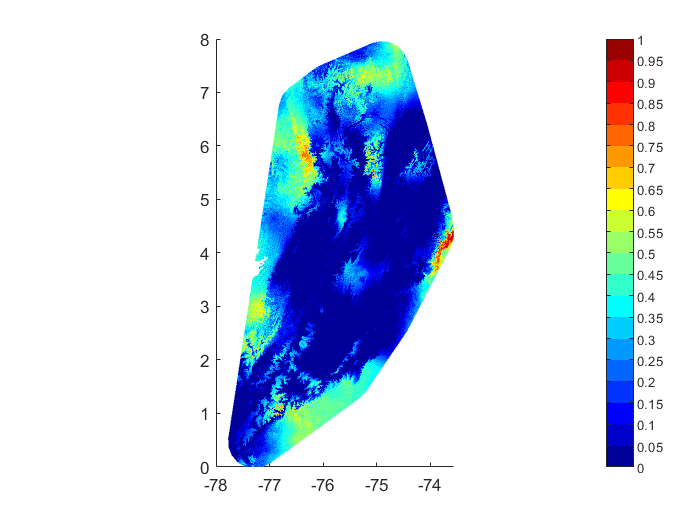

map(:)=distance2;
clf
geoshow(map,R,'DisplayType','surface');
contourcmap('jet',0:0.05:1,'colorbar','on','location','vertical')

2. Muestrear a partir del nuevo mapa

distance4=distance3(nans+1:nans+limit-1);
score=zeros(1,5);
breaks=[1 0.8 0.6 0.4 0.2 0];
factor=0.5;
for i=1:5
    dist1=distance4<breaks(i);
    dist2=distance4>breaks(i+1);
    dist=distance4(logical(dist1.*dist2));
    len=length(dist);
    score(i)=(len/(limit-1))^factor*mean(dist);
end
score=score/sum(score);
samples=200;
score=[0,round(score*samples)];
sampled=zeros(1,samples);

vec=1:limit-1;
len=0;
sscore=cumsum(score);
for i=1:5
    dist1=distance4<breaks(i);
    dist2=distance4>breaks(i+1);
    dist=distance4(logical(dist1.*dist2));
    len(i+1)=len(i)+length(dist);
    sampled(sscore(i)+1:sscore(i+1))=randsample(len(i)+1:len(i+1),score(i+1),true);%muestrear con reemplazo   
end
sampled=sampled+nans;
distance3(:)=0;
distance3(sampled)=1;
distance2(idx)=distance3;
sampled=find(distance2==1);

Extraer latitud y longitud

LAT=NaN(1,length(sampled));
LONG=LAT;
for i=1:length(sampled)
    col=fix(sampled(i)/a);  % integer part
    row=rem(sampled(i),a);  % remainder
    if row>a || col>b
        disp(i)
    end
    [LONG(i),LAT(i)] = pix2map(R,row,col);%!!
end
rem=[isnan(LONG)', isnan(LAT)'];
rem=sum(rem,2);
rem=logical(rem);
LONG(rem)=[];
LAT(rem)=[];

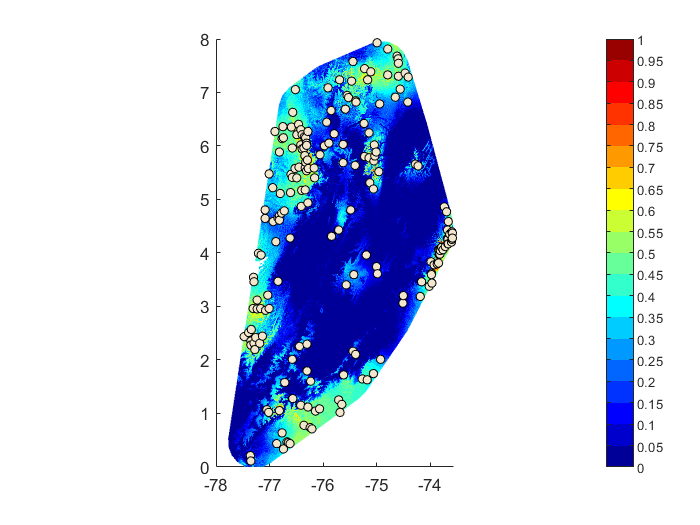

clf
geoshow(map,R,'DisplayType','surface');
contourcmap('jet',0:0.05:1,'colorbar','on','location','vertical')
geoshow(LAT, LONG, 'DisplayType', 'Point', 'Marker', 'o',...
        'MarkerSize',5,'MarkerFaceColor',[.95 .9 .8],'MarkerEdgeColor',...
        'black','Zdata', 2*ones(length(LONG),1));    

3 ahora vamos a probar el rendimiento del algoritmo

T = table('Size',[length(LAT),1],'VariableTypes',{'string'});
T.LAT=LAT';
T.LONG=LONG';
writetable(T,'virtual.csv')

----Reading layers----


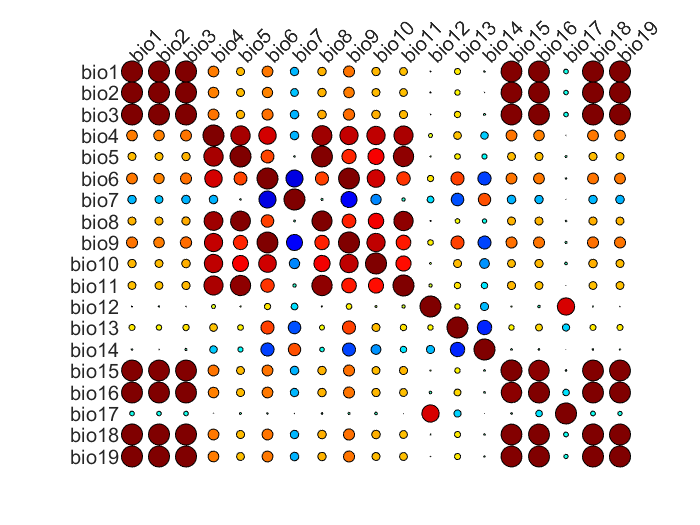

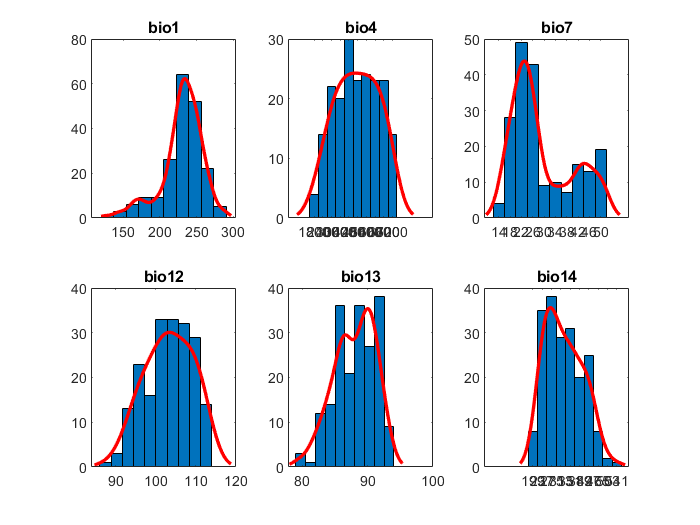

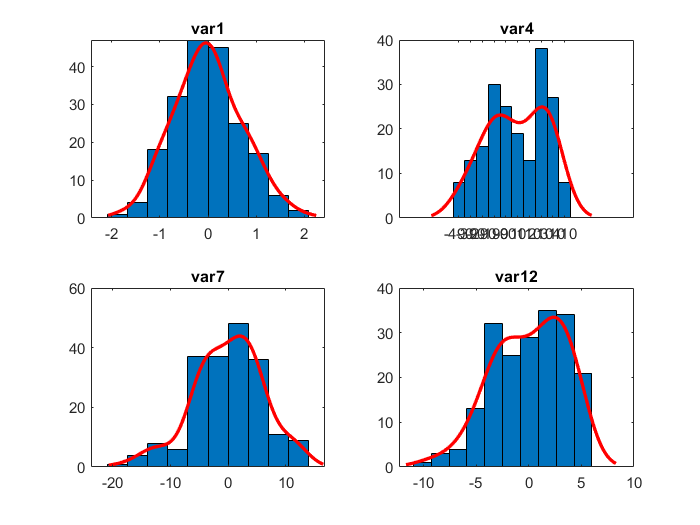

data = struct with fields:
         Tdata: [100×10 table]
    Indicators: [1 4 7 12 13 14]
          Vars: [1 4 7 12]
            T2: [198×22 table]
             Z: [956×507×19 double]
             R: [3×2 double]


doc='virtual.csv';%Ruta al documento de texto con los registros
layerfolder='../data/layers/';%route to folder with ambiental data
show=true;%para mostrar todas las figuras
data = bnm_prep(doc,layerfolder,show,0.7)

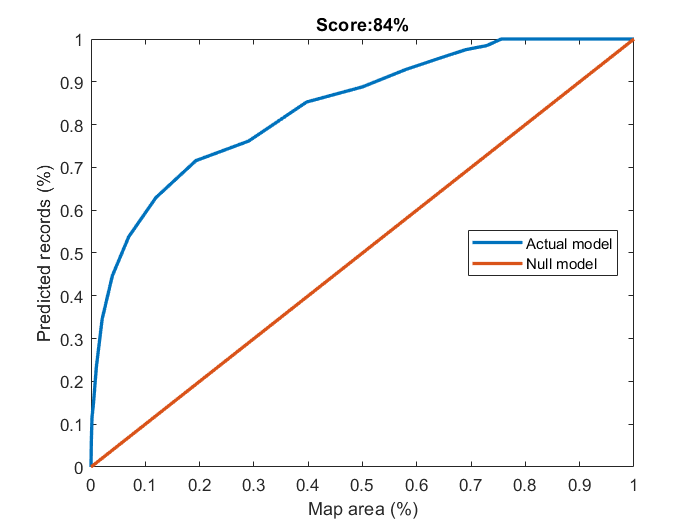

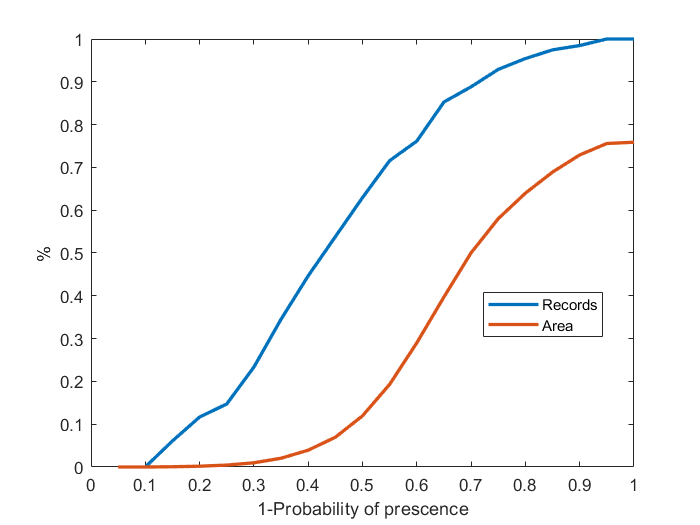

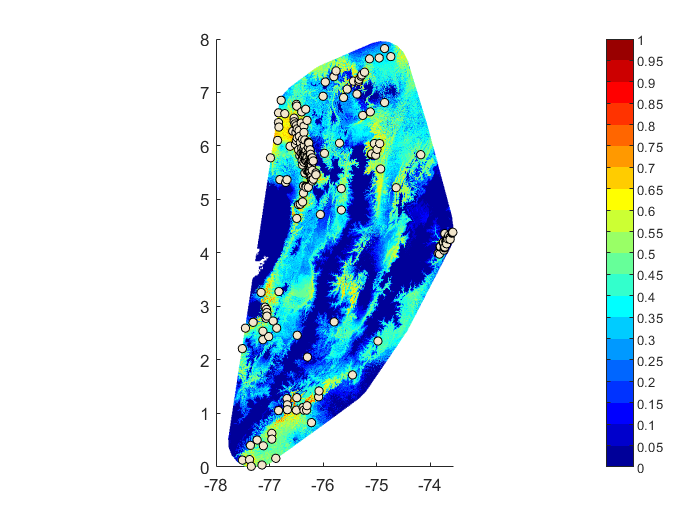

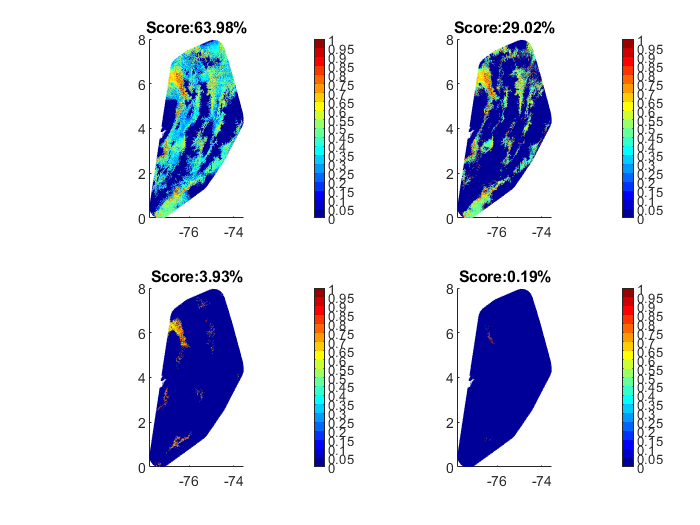

data = struct with fields:
         Tdata: [100×10 table]
    Indicators: [1 4 7 12 13 14]
          Vars: [1 4 7 12]
            T2: [198×22 table]
             Z: [956×507×19 double]
             R: [3×2 double]
           Map: [956×507 double]
      Response: [484692×10 double]
      Minimize: 0.7171
        Method: 4


data = bnm_modeling(data,show)

creación de una métrica para comparar mapas

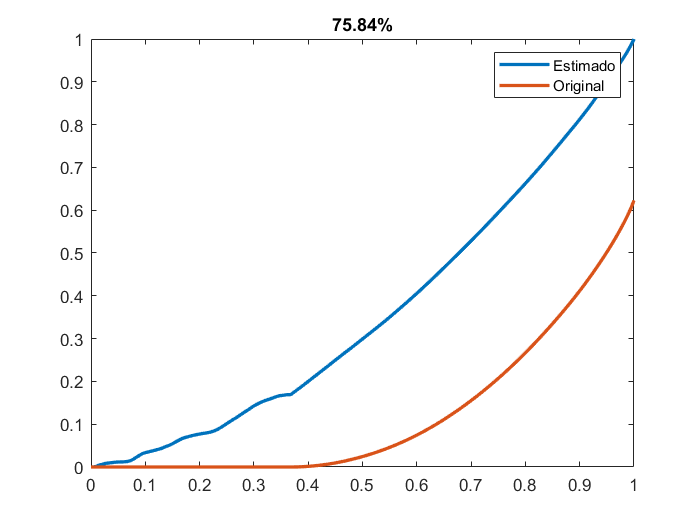

met=mapmet(map,data.Map);

function met = mapmet(map1,map2)
    mapp1=map1(:);
    index=~isnan(mapp1);
    mapp1=mapp1(index);
    mapp2=map2(:);
    mapp2=mapp2(index);
    [mapp1,idx] = sort(mapp1,'ascend');
    mapp2=mapp2(idx);
    mapp2=cumsum(mapp2,'omitnan');
    mapp1=cumsum(mapp1,'omitnan');
    maxim=max(max(mapp1),max(mapp2));
    mapp1=mapp1/maxim;
    mapp2=mapp2/maxim;
    map=abs(mapp1-mapp2);
    x=length(mapp1);
    x=linspace(0,1,x);
    x2=length(map);
    x2=linspace(0,1,x2);
    met=1-trapz(x2,map);
    clf
    plot(x,mapp2,'LineWidth',2)
    hold on
    plot(x,mapp1,'LineWidth',2)
    legend({'Estimado','Original'})
    title(strcat(num2str(round(met*100,2)),'%'))
end